# Medical Physics / Biomedical Engineering 710

## O. Sample Problem -- Prescan Information

First, as a sample problem, we will go over the structure of the raw data folder in a Varian exam. We will illustrate how to read in the header, read in a binary k-space data file, then reconstruct it into a 1-D NMR spectrum. This example will cover the 1-D case, then you will write the 2-D case in the next two problems.

% First, we want to move into the directory where our scans are saved
% On the Varian scanner, these are in the format s_yyyymmdd_ee
% Where y=year, m=month, d=date, e=exam#
% 
% dirname = 's_20121025_01';
% dirname = '.';
% cd(dirname);
% ls;
% 
% Each series is numbered and saved in two directories:
% 01.fid = raw k-space data (fid file)
% 01.img = reconstructed magnitude images (*.fdf files)
% 
% We want to see more detailed information than just the series number
% We can list information about the exam using this custom command:
% load_sdir;
% 
% Load & reconstruct the 1-D NMR Spectrum from Prescan
% 
% Recall that before any MRI images were acquired, we first performed a
% prescan procedure to set the center frequency of the system and calibrate RF power
% from units of amplifier decibels (dB) to units of console (nominal) flip angle.
% 
% Move into the directory where prescan information is stored
% cd('./data');
% ls;
% 
% We can see our two prescan acquisitions: frequency & power
% 
% Move into the prescan frequency directory
% cd('./prescan_freq.fid');
% ls;
% 
% Every raw k-space (fid) directory contains four files:
% 
% Text contains a text description of the pulse sequence used to acquire
% the data. Display the contents of the text:
% type('./text');
% 
% Log is simply a copy of the error & information messages displayed in
% VnmrJ during the scan. This can be used to verify the scan ran correctly.
% Display the contents of the log:
% type('./log');
% 
% fid and procpar are the two files that actually hold scan information
% 
% Procpar is a plain-text file that contains the name and value of every
% parameter defined or computed by the pulse sequence generator (PSG) C-code
% when the 'Start' button is pressed on the scan.
% 
% We can view the procpar directly:
% type('./procpar');
% 
% A more useful way to use this file is to read it into a Matlab data
% structure. Then we can pull up just the parameters of interest when doing
% our analysis. We have a custom command to load this structure:
% info = load_procpar('./procpar');
% 
% For example, we can now easily pull up the TR, TE:
% disp(['The TR is: ' num2str(info.tr*1000) ' ms']);
% disp(['The TE is: ' num2str(info.te*1000) ' ms']);
% 
% Last but definitely not least, fid contains the actual MRI data.
% In this case, our k-space is just a single free induction decay (fid,
% hence the name of the raw data file) used to measure system frequency.
% 
% fid is a binary file, so we cannot look at it directly in the text
% editor as we have for the other files. Instead, we use a special
% command to read in the raw data:
% kspace = load_echoes('./fid');
% 
% Let us start by plotting the first 2000 points of raw k-space.
% Remember that k-space contains complex data, so we need to take the
% magnitude.
% plot(abs(kspace(1:2000)));
% title 'FID Magnitude';
% 
% As expected, it looks more or less like a mono-exponential decay function
% (Note that there are some deviations due to B0 variations caused by shim)
% 
% We can then take the Fourier transform of the data to find the frequency
% spectrum of the sample
% spect = fftshift(ifft(fftshift(kspace)));
% figure;
% 
% subplot(1,2,1);
% frq = (-info.sw/2:info.sw/info.np*2:(info.sw-1)/2); % Build up frequency axis
% plot(frq, abs(spect)); % Plot Spectrum Magnitude
% title 'Sample Frequency Spectrum';
% xlabel 'Offset Frequency [Hz]'
% ylabel 'Signal [a.u.]'
% xlim([-info.sw/2 info.sw/2]);
% 
% subplot(1,2,2);
% frq = (-info.sw/2:info.sw/info.np*2:(info.sw-1)/2); % Build up frequency axis
% plot(frq, angle(spect)); % Plot Spectrum Phase
% title 'Sample Phase';
% xlabel 'Offset Frequency [Hz]'
% ylabel 'Phase [radians]'
% xlim([-info.sw/2 info.sw/2]);
% 
% As expected, it looks like a nice Lorentzian-shaped peak at the NMR
% frequency of the system (note in the plot that 0Hz = 199.75 MHz + 0 Hz,
% since the system already demodulates at the proton frequency).
% 
% We can also look at the prescan power calibration to double-check that it
% follows a nice sinusoidal pattern, and that we are not over-flipping
% (shooting past 180 degrees. This would show up as multiple sinusoids.)
% cd('../prescan_power.fid');
% plot_power();
% 
% Go back to exam directory
% cd('../..');
% load_sdir;

## I. Problem One -- Reconstruct 2D IR Measurements and Generate T1 Maps

The object of the first problem is to generate a T1 map of the phantom, starting from the raw k-space data.

## 1a.) Load Scan Information, Log, and Header Into Matlab

Change directory into the series that contains the inversion recovery T1 experiment. Display the 'text' file to verify that we have used the correct pulse sequence. Display the scan log file to verify that the experiment ran correctly without any warnings or errors.

Then, load in the header and k-space data. Print the following basic scan parameters to the command line: TR, TE, flip angle, and inversion time (TI). Label these with the correct units.

close all
clear all

cd('../..')
hw4dir = 'C:\Users\groberts\Documents\Fall 2018 Classwork\MP710\Homework\MP710_HW_4\MP710_HW_4\s_20121025_01';
cd(hw4dir);                         % Start at home
addpath(genpath('.'))               % Add all subfolders to path
cd('./01.fid');                     % Go in the T1 mapping dataset


type('./text');                     % Pulse sequence info


Spin-echo Multi-slice Imaging sequence


type('./log');                      % Error log


Tue Oct 30 14:10:17 2012: Experiment started
Tue Oct 30 16:18:42 2012: Acquisition complete


info = load_procpar('./procpar');   % Header information

% Output TR, TE, flip angle, and TI:
disp(['The TR is: ' num2str(info.tr*1000) ' ms']);

The TR is: 6000 ms


disp(['The TE is: ' num2str(info.te*1000) ' ms']);

The TE is: 14.84 ms


disp(['The flip angle is: ' num2str(info.flip1) ' degrees']);

The flip angle is: 90 degrees


disp(['The inversion times (TIs) are: ' num2str(info.ti*1000) ' ms']);

The inversion times (TIs) are: 50      81.362538      132.39724      215.44349      350.58055      570.48243      928.31789      1510.6059      2458.1344      4000.0008 ms


## 1b.) Load k-Space Data into Matlab and Reconstruct Images

Load the raw k-space data file into Matlab using our custom command. Display the matrix size on the command line.

kspace = load_echoes('./fid');

Echoes:   128
Readout:  128
Blocks:   10


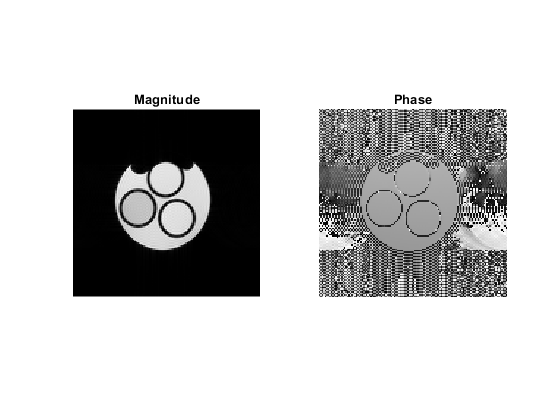


% You will observe that the data size is 128x128x10. This corresponds to a
% readout length of 128 complex-valued points, 128 phase encode lines, and
% 10 different inversion times (aka echoes, readouts, and blocks).
%
% Perform a basic FFT reconstruction on the data to produce images.

data1b = fftshift(ifft2(fftshift(kspace))); 

% Let us take a look at one of the images to verify that the reconstruction
% looks good. Make a figure showing the magnitude and phase images of the first
% TI. Label the images them with appropriate titles and units.
% HINT: Use the subplot() command to show both images in the same figure.

mag1b = abs(data1b);
phase1b = angle(data1b);

figure;
subplot(1,2,1)
imshow(mag1b(:,:,1),[])
title 'Magnitude';
subplot(1,2,2)
imshow(phase1b(:,:,1),[])
title 'Phase';


% HINTS:
%  *If the vial does not appear in the center of the image, you may need to add
%   an extra fftshift() somewhere.
%  *The image phase should appear smooth. If it looks weird or has a
%   "checkerboard" pattern, you may need to add an extra fftshift() somewhere.
%  *The air bubble should appear at the top of the vial (for obvious reasons).
%   If the image appears upside-down, try playing with forward vs. inverse-fft.
%
% You should now have great looking magnitude and phase images.

## 1c.) Investigate How the TI Parameter Affects Image Contrast & Signal

In this section, we will investigate how the image intensity of each vial changes with TI. From now on, we will be dealing only with magnitude images.

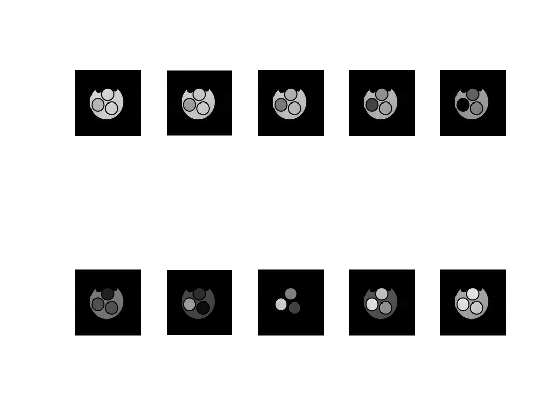

% Start by plotting the image for each TI. Again, use subplot() so that all 10
% images are in the same figure, and label each of them with the appropriate TI.
% All images should be displayed on the same scale, and in gray-scale.

maxPix = ceil(max(max(max(mag1b))));
minPix = floor(min(min(min(mag1b))));

figure;
for i=1:10
    subplot(2,5,i)
    imshow(mag1b(:,:,i),[minPix maxPix])
end


% As TI increases, you should see the contrast between the vials changing.
% Specifically, at different values of TI, each vial, plus the background water,
% will pass through a "null point" where its signal is close to zero.
%
% Next, we want to get a better idea of how the inversion recovery signal curve
% looks for each vial. Draw a region of interest (ROI) in each vial and label
% them the following:
%
% Vial #1 - Lower-Left   (0.40 mM Gd-DTPA)
% Vial #2 - Upper-Middle (0.14 mM Gd-DTPA)
% Vial #3 - Lower-Right  (0.06 mM Gd-DTPA)
%
% Make a plot showing the mean and standard deviation of MRI signal for each
% vial as a function of TI. Try to put all three plots in the same figure if
% possible, and label the axes with the proper units.


Vial #1 - Lower-Left   (0.40 mM Gd-DTPA)

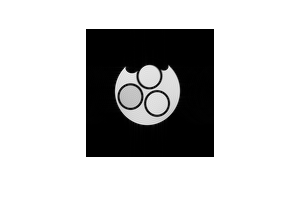

figure;
imshow(mag1b(:,:,1),[])

ROI1 = drawrectangle('Color','g','Label','ROI1');

Undefined function or variable 'drawrectangle'.

i1 = floor(ROI1.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
rows = i1(2):(i1(2)+i1(4));
cols = i1(1):(i1(1)+i1(3));

means1 = zeros(1,10);
for i=1:10
    means1(i) = mean2(mag1b(rows,cols,i));
end

sd1 = zeros(1,10);
for i=1:10
    sd1(i) = std2(mag1b(rows,cols,i));
end


Vial #2 - Upper-Middle (0.14 mM Gd-DTPA)

figure;
imshow(mag1b(:,:,1),[])
ROI2 = drawrectangle('Color','g','Label','ROI2');
i2 = floor(ROI2.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
i2 = [i2(1) i2(2) i2(1)+i2(3) i2(2)+i2(4)];

means2 = zeros(1,10);
for i=1:10
    rows = i2(2):i2(4);
    cols = i2(1):i2(3);
    means2(i) = mean2(mag1b(rows,cols,i));
end
sd2 = zeros(1,10);
for i=1:10
    rows = i2(2):i2(4);
    cols = i2(1):i2(3);
    sd2(i) = std2(mag1b(rows,cols,i));
end


Vial #3 - Lower-Right  (0.06 mM Gd-DTPA)

figure;
imshow(mag1b(:,:,1),[])
ROI3 = drawrectangle('Color','g','Label','ROI3');
i3 = floor(ROI3.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
i3 = [i3(1) i3(2) i3(1)+i3(3) i3(2)+i3(4)];

means3 = zeros(1,10);
for i=1:10
    rows = i3(2):i3(4);
    cols = i3(1):i3(3);
    means3(i) = mean2(mag1b(rows,cols,i));
end
sd3 = zeros(1,10);
for i=1:10
    rows = i3(2):i3(4);
    cols = i3(1):i3(3);
    sd3(i) = std2(mag1b(rows,cols,i));
end


Plot means of each ROI

figure;
subplot(3,1,1)
hold on
plot(means1)
plot(sd1)
hold off
subplot(3,1,2)
hold on
plot(means2)
plot(sd3)
hold off
subplot(3,1,3)
hold on
plot(means3)
plot(sd3)
hold off





% Note again that each vial has a "null point" at a different location on the TI
% axis. Also note that, unlike the plot shown in lecture slides, these curves to
% not start at -Mz and relax back to +Mz. The values of these curves are always
% positive. This is due to the magnitude operation used to reconstruct image.

## 1d.) Fitting IR Signal to Compute T1

Now we are going to fit the inversion recovery data at each voxel to a mathematical model of the MRI signal evolution. Instead of generating an MRI image of the phantom, with different signal contrasts for each vial, we are now going to generate a quantitative "map" showing estimates of the actual T1 times. The goal of this question is to produce maps of proton density and T1.

Because we have taken the magnitude operation on the data, we cannot simply fit it to an exponential recovery curve, but instead must use nonlinear least-squares fitting.

You will have to find a mathematical model for the MRI signal as a function of inversion time (and any other relevant parameters). These should be read directly from the image header. You will also need to use a Matlab routine to fit the MRI data to this model, and generate two images: PD and T1 HINT: If you are having trouble with the fitting, try looking up Matlab documentation for "nonlinear least-squares solver"

% Some code is provided to get started.

% Loop over each voxel in the image.
for ii = 1:size(image, 1)
  for jj = 1:size(image, 2)
    
    % Keep track of progress
    progressbar(ii/(size(image,1)+1));
    
    % Grab the MRI data from each TI for this voxel
    vox_data = double(squeeze(abs(image(ii,jj,:))))';
    
    % Nonlinear solvers are typical "local," which means they need to be given
    % an initial guess that is close to the correct answer so that they do not
    % "diverge" away from the true answer.
    %
    % HINT: For the PD initial guess, think of which TI image gives signal that
    % is closest to a proton-density weighted image.
    %
    % HINT: For the T1 initial guess, think about the null point. Recall from
    % previous lectures and courses how the parameter TI can be chosen in a
    % FLAIR image to null out signal from certain tissues. How is this "null TI"
    % computed?
    
    % <initial guess code here>

    % Next, we need to program in a mathematical model of the MRI signal as a
    % function of TI. If you are familiar with "anonymous functions" in Matlab,
    % this model can be written directly in this file, otherwise write it as a
    % separate Matlab function and call it t1_model.m
    
    % <t1 model code here>

    % Finally, use a nonlinear least-squares solver to fit the data to the
    % model, using the initial guess as a starting point.
    
    % <solver code here>
    
    % Assign the results of the fitting to two output variables: pd and t1
    pd(ii,jj) = pd;
    t1(ii,jj) = t1;
  end
end

% Close the progress bar
progressbar(1);

## 1e.) Analyze Results of T1 Mapping in a Variety of Ways

Now that we have fitted our MRI data to the inversion recovery model, we now want to visualize and analyze our results in a number of ways. For starter's let's look at images of PD and T1 maps. As before, display both images on the same figure using subplot(). Put a color scale bar on each image and label them with appropriate units. Mask out the background noise so that it is easier to observe the actual phantom.

% <code here>

% Look at the maps and make sure that they are okay. Here are some hints to know
% that everything worked correctly:
%
% *The range of T1 should be between 0 and 3 seconds (the T1 of water at
%  4.7T is about 3s)
%
% *Each of the three vials + background water should have a different T1 time.
%  The water in the background should have the longest T1.
%
% *Within each vial, the T1 should be fairly uniform. There maybe be some
%  pixes at the edges that have noise, but if there are large variations in
%  T1, "noise," or unreasonable values, you should look at the initial guess
%
% Often times in quantitative MRI, we do "region of interest" analysis. This just
% means we look at the average T1 value over a specific region of the brain or
% body to see if any abnormalities are observed.
%
% Compute the mean and standard deviation of both PD and T1 using the regions of
% interest from 1c. Print out these values, making sure to label proper units!

% <code here>

% Finally, display the fitted IR curve on top of the actual MRI data
% points (similar to what we did in 1c, but use the fitted results of PD
% and T1 to "fill in the curve" in-between actual data points).
% Label the axes with the proper names and units.

% <code here>

% Congradulations! You have just completed your first T1 mapping experiment.
cd('../');
load_sdir;

## II. Problem Two -- Reconstruct 2D Spine Echo Measurements and Generate T2 Maps

The object of the second problem is to generate a T2 map of the phantom, starting from the raw k-space data file.

## 2a.) Load Scan Information, Log, and Header Into Matlab

Change directory into the series that contains the spin echo T2 mapping experiment. Display the 'text' file to verify that we have used the correct pulse sequence. Display the scan log file to verify that the experiment ran correctly without any warnings or errors.

Then, load in the header and k-space data. Print the following basic scan parameters to the command line: TR, TEs, flip angle. Label these with the correct units.

% <code here>

## 2b.) Load k-Space Data into Matlab and Reconstruct Images

Load the raw k-space data file into Matlab using our custom command. Display the matrix size on the command line.

% <code here>

% You will observe that the data size is 128x128x10. This corresponds to a
% readout length of 128 complex-valued points, 128 phase encode lines, and
% 10 different echo times (aka echoes, readouts, and blocks).
%
% As in (1b), perform a basic FFT reconstruction on the data to produce images.

% <code here>

% Next, let us take a look at our images to verify that our reconstruction looks
% good. Make a figure showing the magnitude and phase images of the first TE.
% Label the images them with appropriate titles and units.

% <code here>

% You should now have great looking magnitude and phase images.

## 2c.) Investigate How the TE Parameter Affects Image Contrast & Signal

In this section, we will investigate how the image intensity of each vial changes with echo time. From now on, we will be dealing only with magnitude images.

image = abs(image);

% Start by plotting the image for each TE. Again, use subplot() so that all 10
% images are in the same figure, and label each of them with the appropriate TE.
% All images should be displayed on the same scale, and in gray-scale.

% <code here>

% Unlike the case for the IR experiment, increasing TE does not create "null
% points" or drastically change the contrast of signal between the vials.
% Instead, the overall signal intensity gradually declines as TE becomes longer.
%
% Let's make a plot showing the mean and standard deviation of MRI signal for
% each vial as a function of TE, so we can better visualize how the signal is
% changing. Try to put all three plots in the same figure if possible, and label
% the axes with the proper units. Use the ROIs defined from #1.

% <code here>

% As expected, the signal slowly decays away as TE increases. Although it may
% not be readily apparent, these data points follow the shape of a
% mono-exponential decay curve. We simply have not sampled a long enough TE to
% see the signal decay away to a value near zero.

## 2d.) Fitting Spin-Echo Signal to Compute T2

Now we are going to fit the spin echo data at each voxel to a mathematical model of the MRI signal evolution.

This time, the signal follows a more simple mathematical function that can be cast into a linear form. Thus, we do not need to use the complicated nonlinear least squares methods as done in Problem 1. Instead, you should find a transform to make the signal linear, then use standard least-squares regression to fit the model to the signal.

% As before, some code is provided to get started.

% Loop over each voxel in the image.
for ii = 1:size(image, 1)
  for jj = 1:size(image, 2)
    
    % Keep track of progress
    progressbar(ii/(size(image,1)+1));
    
    % Grab the MRI data from each TE for this voxel
    vox_data = double(squeeze(abs(image(ii,jj,:))))';
    
    % <code here>
    
    % Assign the results of the model to two output variables: pd and t2
    pd(ii,jj) = pd;
    t2(ii,jj) = t2;
  end
end

% Close the progress bar
progressbar(1);

## 2e.) Analyze Results of T2 Mapping in a Variety of Ways

Now that we have fitted our MRI data to the spin echo model, we now want to visualize and analyze our results in a number of ways. Display T2 and proton density maps on the same figure using subplot(). Put a color scale bar on each image and label them with appropriate units. Mask out the background noise so it is easier to observe the actual phantom.

% <code here>

% *The range of T2 should be between 0 and 600 milliseconds
% *Each of the three vials + background water should have a different T2 values.
%
% Compute the mean and standard deviation of both PD and T1 using the regions of
% interest from 1c. Display these values, making sure to label units!

% <code here>

% Finally, display the fitted spin echo signal on top of the actual MRI data
% points (similar to what we did in 1e, but for PD and T2).
% Label the ordinate and abscissa with the proper names and units.
% Extrapolate your fitted signal curve all the way out to 1000 ms.

% <code here>

% Congratulations! You have just performed your first T2 mapping experiment.
cd('..');
load_sdir;

## III - Appendix

Series #1 and #2 are all that are needed to complete this assignment. However, during the laboratory, we also acquired some additional scans. These have been included in case you would like to play around with the data.

In particular, you should look at the k-space of the EPI scan. It is very different from the scans we have just looked at. EPI is difficult to reconstruct, however a custom command has been provided to load the images that were reconstructed on the scanner:

epi_05 = load_fdf('05.img/slice001image001echo001.fdf',1);
epi_06 = load_fdf('06.img/slice001image001echo001.fdf',1);
epi_07 = load_fdf('07.img/slice001image001echo001.fdf',1);

figure;
subplot(1,3,1);
imagesc(epi_05);
axis image; axis off;
colormap gray;
title 'Gradient Echo EPI, 1-Shot';
subplot(1,3,2);
imagesc(epi_06);
axis image; axis off;
colormap gray;
title 'Gradient Echo EPI, 4-Shots';
subplot(1,3,3);
imagesc(epi_07);
axis image; axis off;
colormap gray;
title 'Spin Echo EPI, 4-Shots';

## IV. -- Handing In The Assignment

When you have competed this assignment to your satisfaction, do the following:

1.) Save a copy of this M-file with your name. 2.) Go to File->Publish. This will run the code over from the very beginning, and will generate an html file of your code and png images of your figures. Depending on your Matlab version, these may be saved in a folder called 'html' 3.) Zip up these files, along with the M-file, and e-mail them in to Professor Wieben